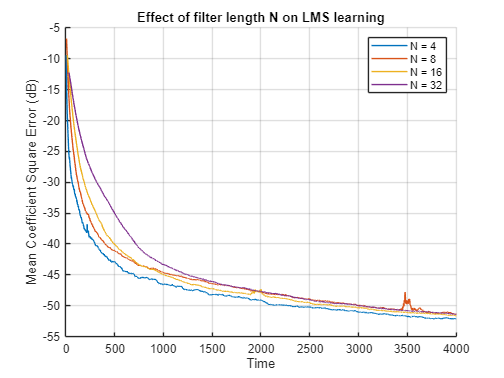

Ns = [4, 8, 16, 32];  
R = 4000;
NAvr = 100;
qv = 0.01;
qu = 1;
sw = 1;
h = [1; 1/2];

% algorithm parameters
alpha = 1/3;
k = 2;

figure;
hold on;

for n_idx = 1:length(Ns)
    N = Ns(n_idx);
    w_msq_log = zeros(R, NAvr);

    wo=(1.1*sinc((0:N-1)-10.7)-0.7*sinc((0:N-1)-13.2)+0.5*sinc((0:N-1)-5.3))';
    wo=sw*wo/sqrt(sum(wo.^2));

    for i=1:NAvr
        rng(1000+i);
        s = randn(1, R + length(h) - 1);
        u = sqrt(qu)*conv(s,h)/sqrt(sum(h.^2));
        u = u(length(h):end);
        v = sqrt(qv)*randn(R,1);

        w = zeros(N,1); w(1)=1;
        uv = zeros(N,1);
        qo = [10 10]';
        A = zeros(2);
        b = zeros(2,1);

        for n = 1:R
            uv = [u(n) uv(1:N-1)']';
            d = uv'*wo + v(n);
            e = d - uv'*w;

            if n > N
                [w, qo, A, b, mu] = BSLMS(uv, d, w, qo, A, b, N, alpha, k);
                w_msq_log(n,i) = mean((w - wo).^2);
            end
        end
    end

    % 畫出每個 N 的平均 MSE 收斂曲線
    plot(10*log10(mean(w_msq_log,2)), 'DisplayName', sprintf('N = %d', N));
end

xlabel('Time');
ylabel('Mean Coefficient Square Error (dB)');
legend;
title('Effect of filter length N on LMS learning');
grid on;

function [w, qo, A, b, mu] = BSLMS(uv, d, w, qo, A, b, N, alpha, k)

    delta = 1e-9;   
    ddelta = 1e-99; % 加在除法分母裡防止出現 NaN 或 Inf
 
    e = d - uv'*w;  % error

    %% q measure update

    PT = uv'*uv + ddelta;
    P = PT/N;
    a = [PT, 1]';

    inv_zeta_sq_times_2 = 1/(2*(a'*qo)^2 + ddelta);

    A = A + inv_zeta_sq_times_2*(a*a');   %% equ29
    b = b + inv_zeta_sq_times_2*e^2*a;    %% equ30

    qo = (A+(ddelta+delta*trace(A))*eye(2)) \ b;

    xi = b'*qo;  % equ.26
    c = b/xi;    % equ.25
    nx = 4*xi/k;
    
    % equ.46
    z = qo(1)/(qo(1)*PT+qo(2));  
    if z < 0
        z = 0;
    end
    if z > 1/PT
        z = 1/PT;
    end
    

    %% Calculate mu=E[z]
    if nx <= 4 
        mu = z;
    else % Laplace Approximation 
        % first derivative
        d1 = ...
            -(nx*(pi*z*(A(1,1) - 2*PT*A(1,2)) + pi*(z*A(1,1) - 2*(-1 + PT*z)*A(1,2)) + ...
            2*pi*PT*(-1 + PT*z)*A(2,2)))/...
            (4.*(pi*z*(z*A(1,1) - 2*(-1 + PT*z)*A(1,2)) + pi*power(-1 + PT*z,2)*A(2,2))) + ...
            ((-4 + nx)*(c(1) - PT*c(2)))/(2.*(z*c(1) + c(2) - PT*z*c(2)));

        % second derivative
        d2 = ...
            -((-4 + nx)*power(c(1) - PT*c(2),2)*power(z*c(1) + c(2) - PT*z*c(2),-2))/2. + ...
            (nx*power(pi*z*(A(1,1) - 2*PT*A(1,2)) + pi*(z*A(1,1) - 2*(-1 + PT*z)*A(1,2)) + ...
            2*pi*PT*(-1 + PT*z)*A(2,2),2)*power(pi*z*(z*A(1,1) - 2*(-1 + PT*z)*A(1,2)) + ...
            pi*A(2,2)*power(-1 + PT*z,2),-2))/4. - ...
            (nx*(2*pi*(A(1,1) - 2*PT*A(1,2)) + 2*pi*A(2,2)*power(PT,2))*...
            power(pi*z*(z*A(1,1) - 2*(-1 + PT*z)*A(1,2)) + pi*A(2,2)*power(-1 + PT*z,2),-1))/4;

        
        if d2 >= 0
            mu = 1/(2*PT);  % at the middle of the interval
        else

            z0  = z - d1 / d2;   % z0 is approximately equal to z at the maximum
            pz = - d2;           % equ.66

            ax = sqrt(pz)*(1-z0*PT)/(sqrt(2)*PT);  % equ.67
            bx = z0*sqrt(pz)/sqrt(2);

            if ax+bx < 1e-9   % equ.68-71
                mu = 0; % lim a -> -b
            elseif abs(ax) > 10 && abs(bx) > 10  ...
                    && sign(ax)<0 && sign(bx)>0 % erfc saturates at 0
                mu = z0 + (-2+2*exp(-bx^2+ax^2))/...
                    (sqrt(2*pi*pz)*(...
                    -exp(-1/(2*ax^2))/(sqrt(pi)*ax)+...
                    -exp(-bx^2+ax^2-1/(2*bx^2))/(sqrt(pi)*bx)));
                % erfc(x) +-= exp(-x^2-1/(2x^2))/(sqrt(pi)*x)
            elseif abs(ax) > 10 && abs(bx) > 10  ...
                    && sign(ax)>0 && sign(bx)<0 % erfc saturates at 0
                mu = z0 + (-2*exp(bx^2-ax^2)+2)/...
                    (sqrt(2*pi*pz)*(...
                    -exp(bx^2-ax^2-1/(2*ax^2))/(sqrt(pi)*ax)+...
                    -exp(-1/(2*bx^2))/(sqrt(pi)*bx)));
                % erfc(x) +-= exp(-x^2-1/(2x^2))/(sqrt(pi)*x)
            elseif abs(ax) > 3 && abs(bx) > 3  ...
                    && sign(ax)*sign(bx) == -1 % erfs saturates at +1 and -1
                mu = z0 + (-2*exp(-ax^2)+2*exp(-bx^2))/...
                    (sqrt(2*pi*pz)*(...
                    -sign(ax)*erfc(abs(ax))+...
                    -sign(bx)*erfc(abs(bx))));
            else
                mu = z0 + (-2*exp(-ax^2)+2*exp(-bx^2))/...
                    (sqrt(2*pi*pz)*(erf(ax)+erf(bx)));
            end
           
        end
    end
    
    w = w + mu*uv*e;  % LMS central equ.


    gamma1 = 1;
    if qo(1) < 0
        gamma1 = -1;
    end
    gamma2 = 1;
    if qo(2) < 0
        gamma2 = -1;
    end
    
    %% Time Update
    C = [gamma1*(1-alpha*mu*P)^2, gamma2*alpha*mu^2*P;...
                         0,              gamma2]; % equ.59

    C1 = inv(C);  
    A = C1'*A*C1;  % equ.60
    b = C1'*b;     % equ.61

    %% Limit A , equ.62
    if trace(A) > 1e11  % assume max_trace(A) = 1e11
        kx = 1e11/trace(A);
        A = kx*A;
        b = kx*b;
    end
end
